# Lista 5 

**Zad. 1. **Obiekt porusza się ruchem jednostajnym prostoliniowym wzdłuż osi *x* z prędkością 10 m/s. Sporządź dwa wykresy: zmiany położenia w czasie $x\left(t\right)$ i zmiany prędkości w czasie $v\left(t\right)$. Dodatkowo na wykresie zmian położenia od czasu narysuj wektory prędkości co 1 s. (Rysunek ma wyglądać podobnie, jak rysunek poniżej.)

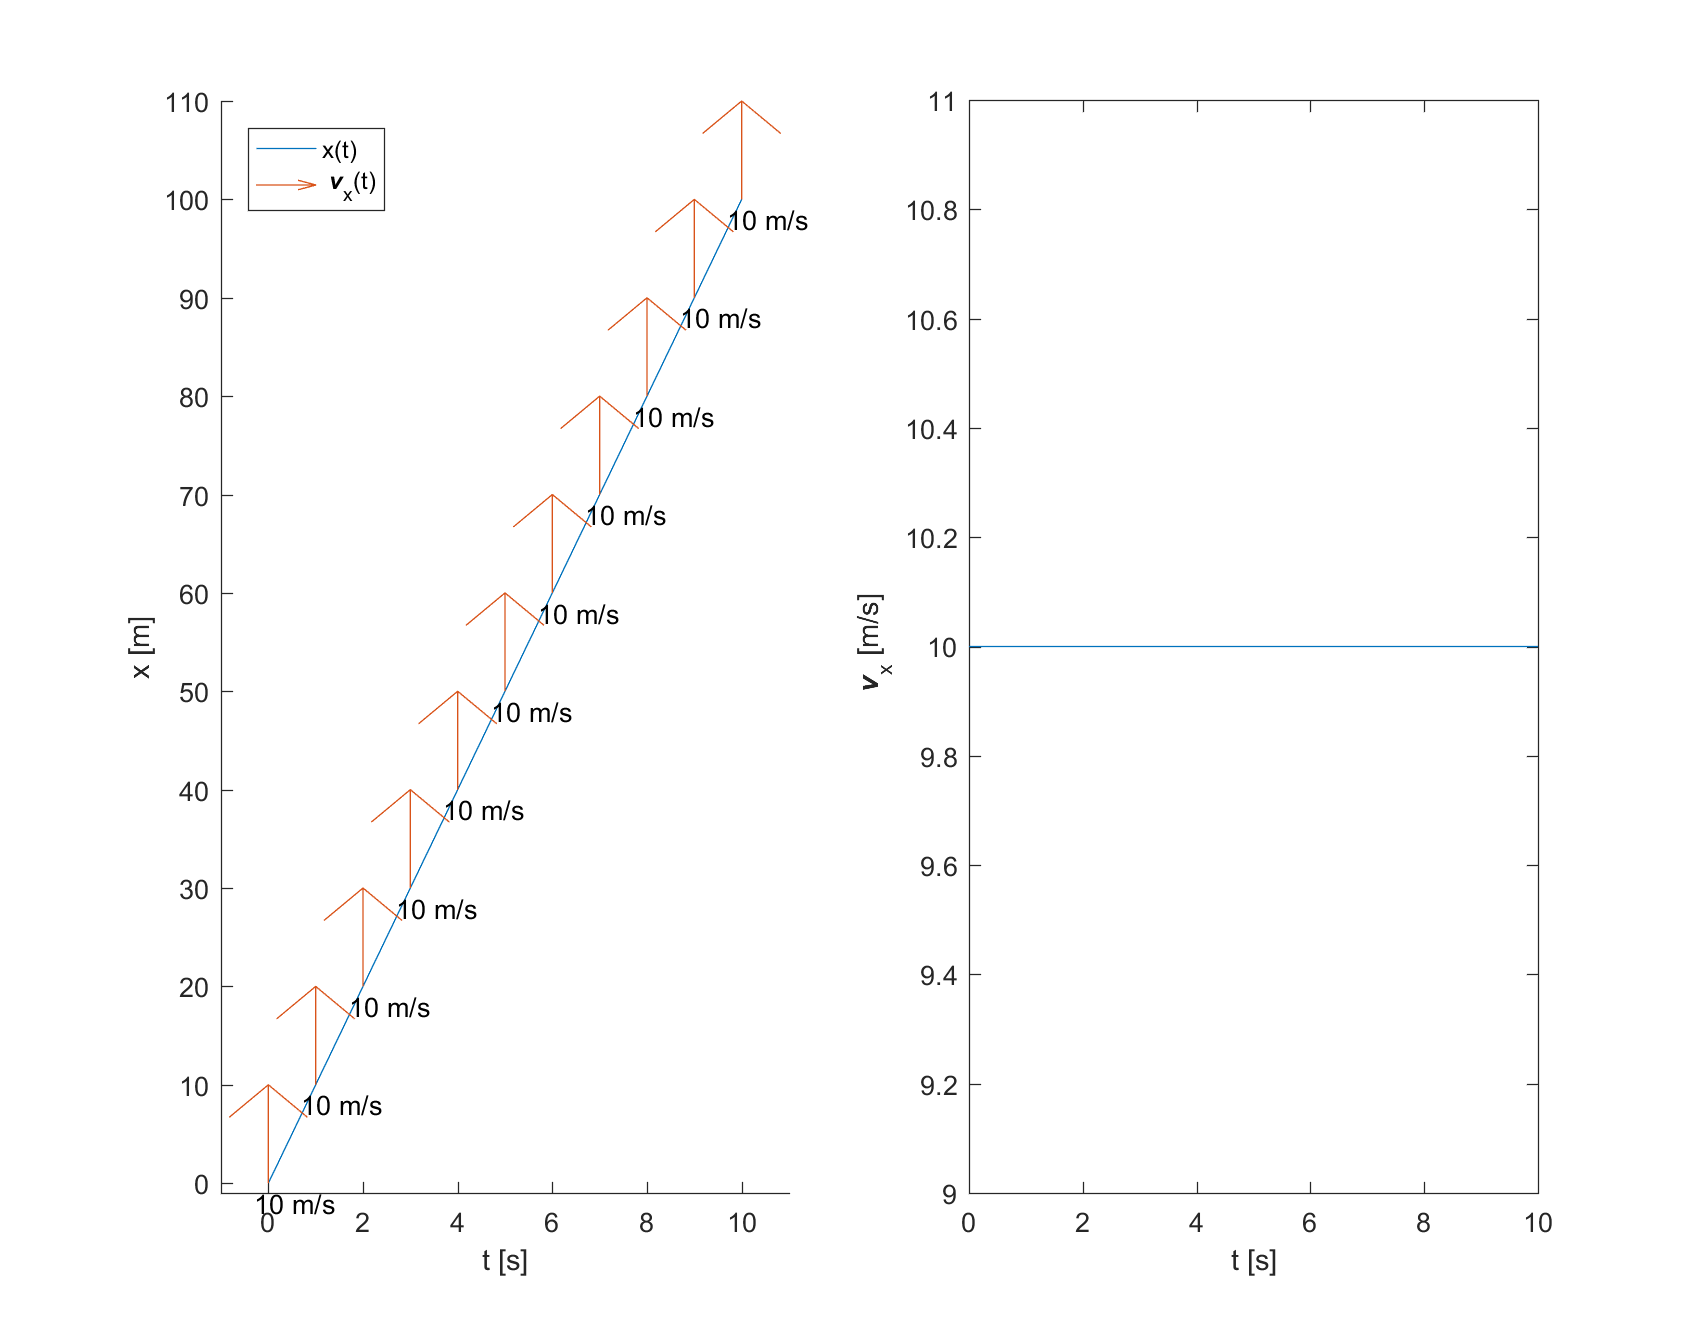

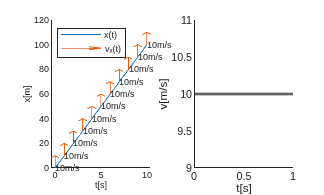

clf;
x = linspace(0,100,100);
t = linspace(0,10,100);
v = 10;

subplot(1,2,1);
hold on;
plot(t,x)

q_t = [0:10];
q_x = [0:10:100];

q_u = zeros(1,11);
q_v = ones(1,11).*10;

quiver(q_t,q_x, q_u,q_v, 0, "MaxHeadSize",0.05);

text(q_t,q_x,"10m/s");
legend("x(t)","v_x(t)", Location="northwest");
xlabel("t[s]");
ylabel("x[m]");
fontsize(9,"pixels");

ylim([0 120]);

hold off

subplot(1,2,2);
yline(v,"LineWidth",2);
xlabel("t[s]");
ylabel("v[m/s]");

**Zad. 2.** Obiekt został rzucony pionowo do góry z prędkością początkową $v_{\mathrm{y0}} =10$ m/s.

- Sporządź dwa wykresy: zmiany wysokości od czasu $y\left(t\right)$ oraz zmiany prędkości od czasu $v_y \left(t\right)$.  Dodatkowo na wykresie zmian położenia w czasie narysuj wektory prędkości co 0.25 s. (Rysunek ma wyglądać podobnie, jak rysunek poniżej.)

- Jaka jest maksymalna wysokość obiektu, kiedy ją osiągnie i jaką będzie miał wtedy prędkość? Umieść te wartości na wykresie.

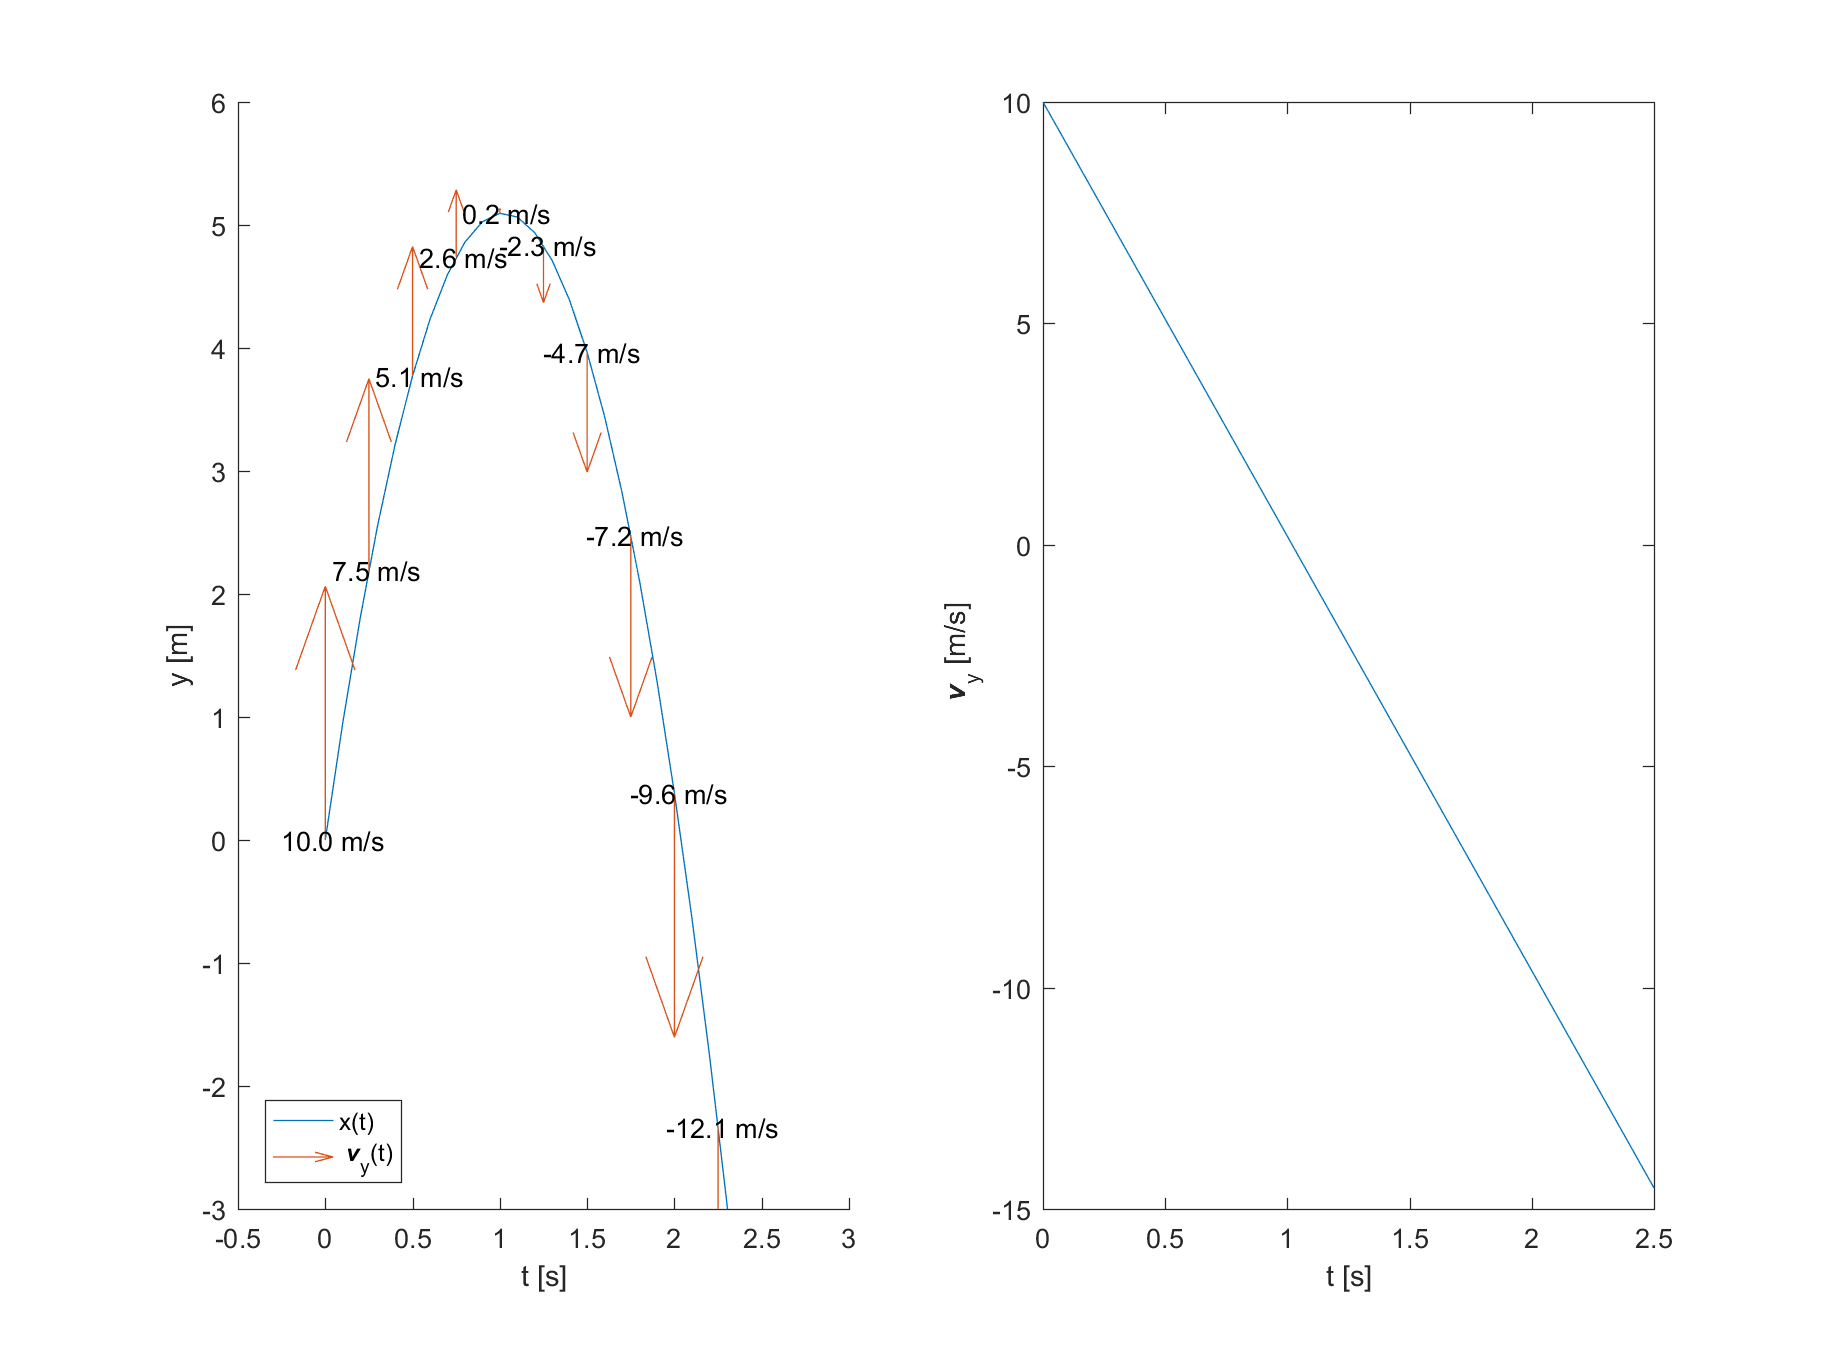

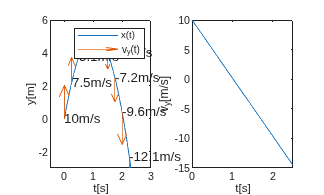

clear;
clf;
t = linspace(0,2.5,100);
v_y0 = 10;
g = 9.81;

y = v_y0 .*t + 0.5 .* -g .* t.^2;

subplot(1,2,1)
plot(t,y);

hold on;
ylim([-3 6]);
xlim([-0.5 3]);

ylabel("y[m]");
xlabel("t[s]");

q_t = [0:0.25:2.25];
q_vy = round(v_y0 - g .* q_t, 1);
q_y = v_y0 .*q_t + 0.5 .* -g .* q_t.^2;

q_u = zeros(size(q_t));

text(q_t,q_y,q_vy + "m/s");

quiver(q_t,q_y, q_u,q_vy, 1);
legend("x(t)", "v_y(t)");
hold off;

% ---

v_y = v_y0 - g .* t;
subplot(1,2,2);
plot(t,v_y);
ylim([-15 10]);
xlim([0 2.5]);
ylabel("v_y[m/s]");
xlabel("t[s]");